# Task 3 - Number plate recognition

## Pre-processing

### Read images and turn them to grayscale

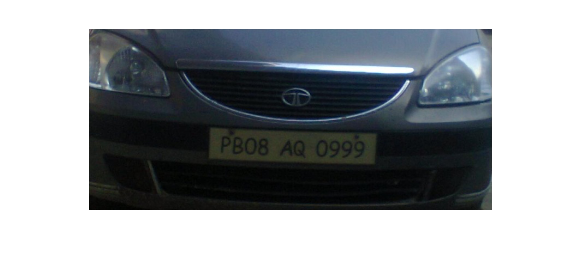

img_path = "images/final/task_3/";

image1 = imread(img_path + "example_number_plate.png");
imshow(image1);

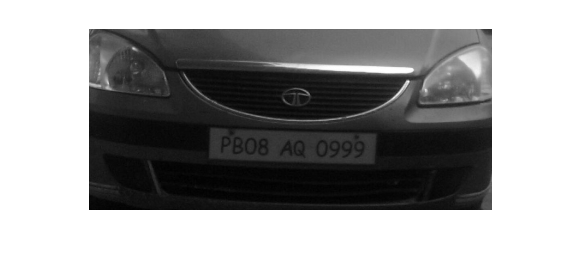


img1gray = rgb2gray(image1);
imshow(img1gray);

### Noise removal

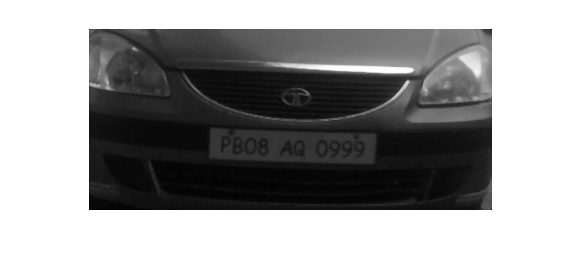

% Here I guess we could use imbilatfilt to filter it 
% bilaterally like in the documentation.
img1med = medfilt2(img1gray);
imshow(img1med);

### Contrast Enhancement 

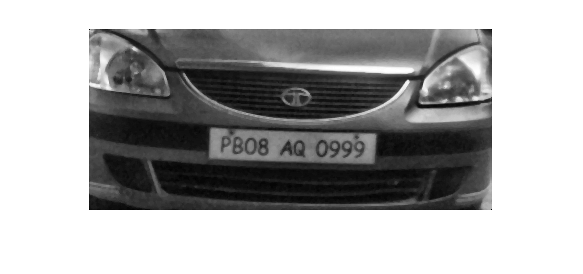

img1cont = adapthisteq(img1med);
imshow(img1cont);

## Morphological Opening and Image Subtraction Operations

### Opening with 'disk'

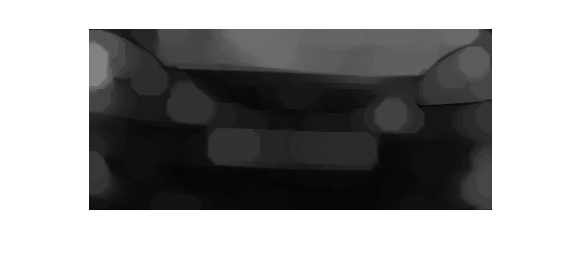

se = strel('disk',15);
img1open = imopen(img1cont,se);
imshow(img1open);

### Subtraction from enhanced image

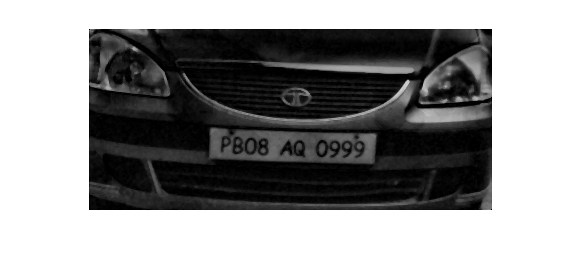

img1sub = imsubtract(img1cont, img1open);
imshow(img1sub);

## Image binarization

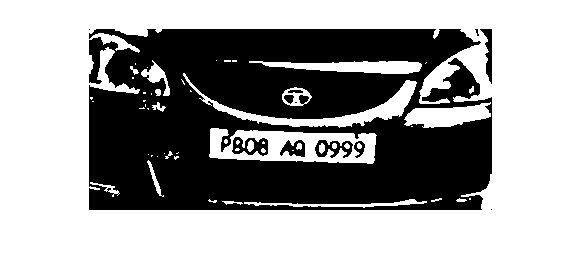

img1bin = imbinarize(img1sub);
imshow(img1bin);

## Detect edges with the Sobel operator

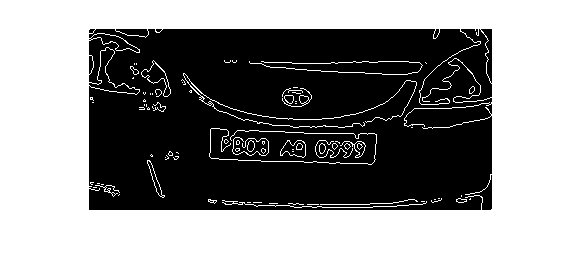

img1edge = edge(img1bin);
imshow(img1edge);

## Candidate plate area detection with morphological operators

### Dilation

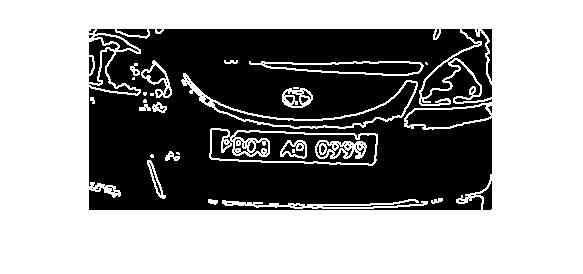

se2 = strel('square', 2);
img1dil = imdilate(img1edge, se2);
imshow(img1dil);

### Filling holes

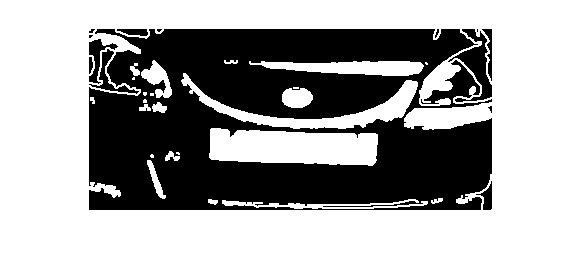

img1fill = imfill(img1dil, 'holes');
imshow(img1fill);

### Opening

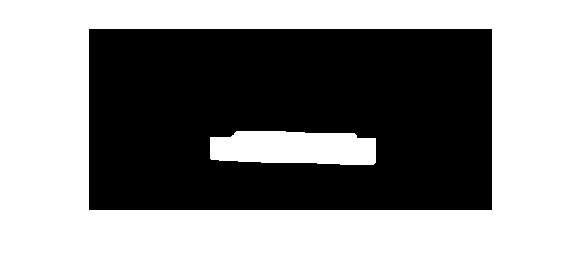

se3 = strel('square',22);
img1open = imopen(img1fill, se3);
imshow(img1open);

### Erosion

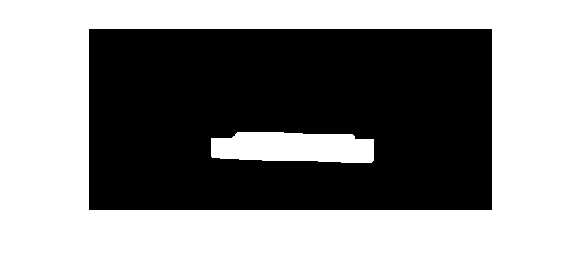

% This does not seem necessary.
se4 = strel('square', 4);
img1erode = imerode(img1open,se4);
imshow(img1erode);